Plot Front

proccessed = experiment1;
fpms = 50;
totalTime = size(experiment1, 3)/fpms;
msPerFrame = 1/fpms;
micronsPerXPixel = 13.5;
micronsPerZPixel = 50;

%-- smooth over space time for errors
smoothed = smooth3(proccessed, 'box', [7 7 3]);
front = zeros(size(smoothed,1), size(smoothed,2), size(smoothed,3));
for i=1:size(smoothed,1)
    for j=1:size(smoothed,2)
        for k=1:size(smoothed,3)
            front(i,j,k) = smoothed(i,j,k) > 0.97 && smoothed(i,j,k) < 0.98;
        end
    end
end

front = medfilt3(front, [5 5 1]);


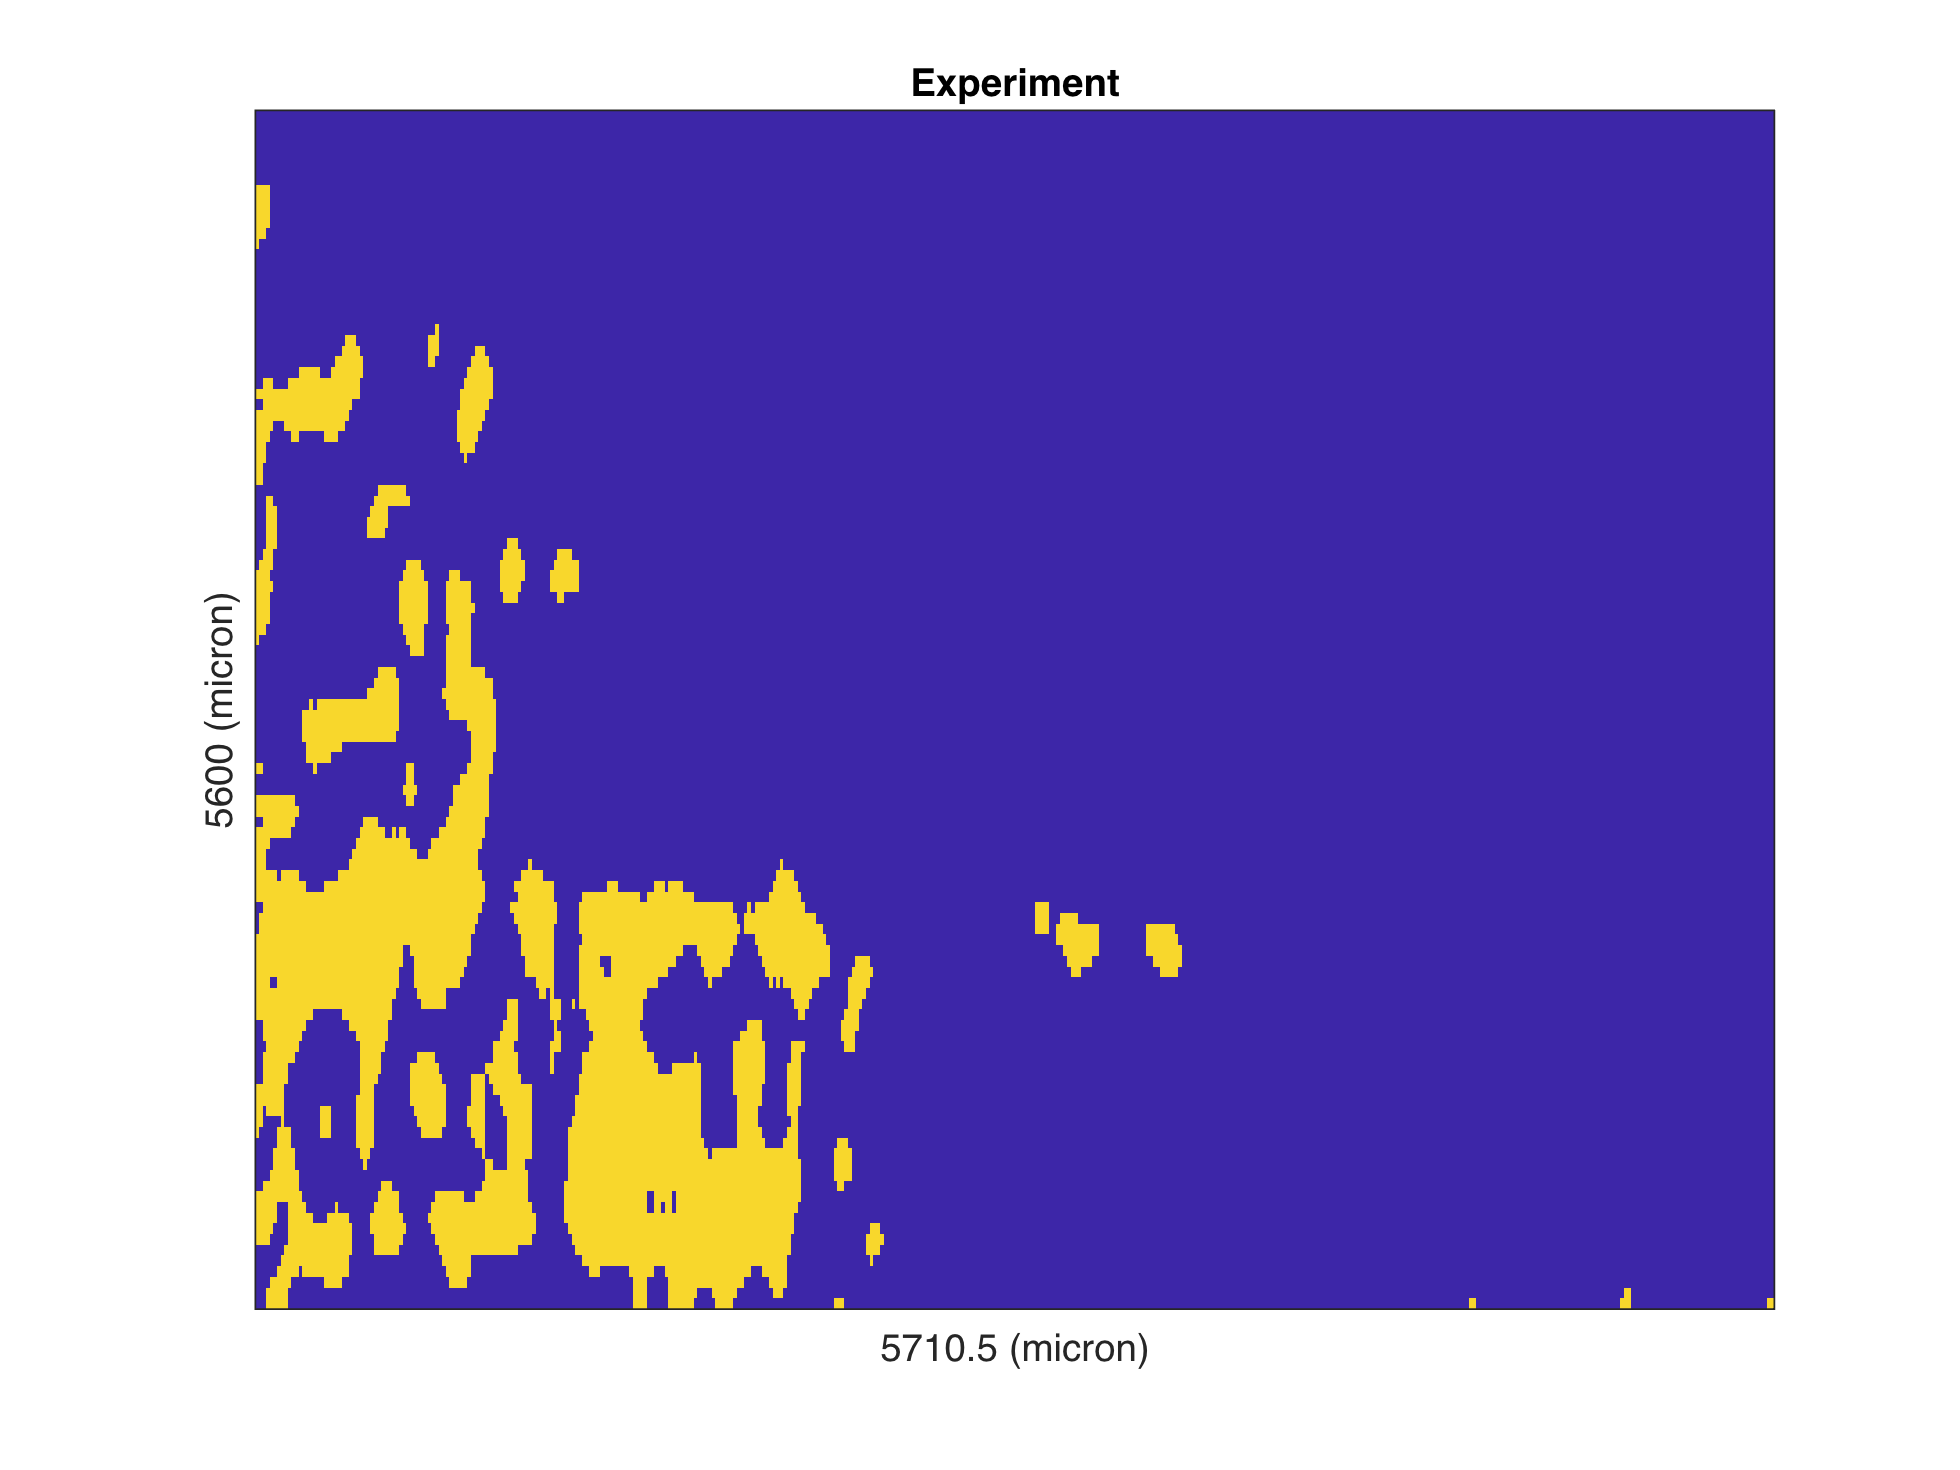

%-- plot front
t=1.34;
current = front(:,:,round(t*fpms)+1);
imagesc(current);
caxis([0.9 1.01]);
if(~smoothing)
    colorbar;
end
title("Experiment");
xticks([]);
yticks([]);
xlabel(micronsPerXPixel * size(experiment1,2) + " (micron)");
ylabel(micronsPerZPixel * size(experiment1,1) + " (micron)");

binFront = logical(current);
skeleton = bwskel(binFront);
imagesc(skeleton);